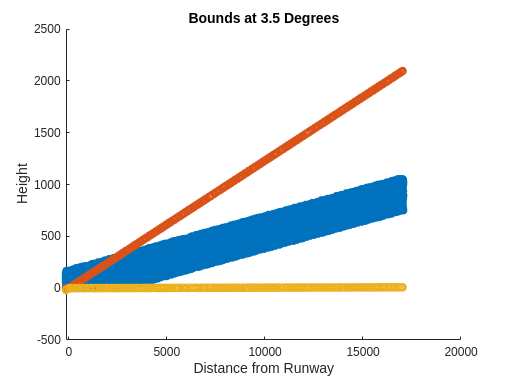

clear variables; close all; clc;
data = readtable("/media/storage_drive/ULI Datasets/dataWPI_17000/states.csv");
x = data.Var4;
h = data.Var6 - 361;
y = data.Var5;
h_start = 1411 - 361;
slope = h_start / 17000;
slope_x = x.*slope;
r = tand(3.5) * sqrt(x.^2 + slope_x.^2);
u_bounds = slope_x + r;
l_bounds = slope_x - r;

scatter(x, h);
hold on;
scatter(x, u_bounds);
scatter(x, l_bounds);
xlabel("Distance from Runway");
ylabel("Height");
title("Bounds at 3.5 Degrees");
hold off;

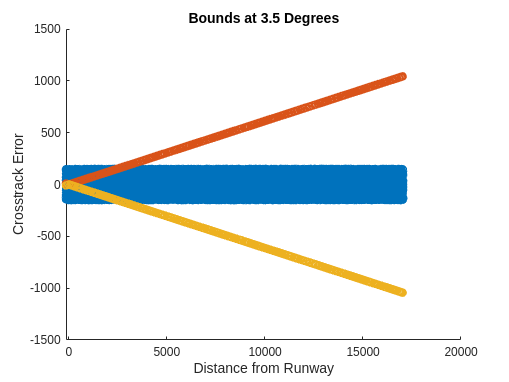


scatter(x, y);
hold on;
scatter(x, r);
scatter(x, -r);
xlabel("Distance from Runway");
ylabel("Crosstrack Error");
title("Bounds at 3.5 Degrees");
hold off;